clear all; close all;

## Load data

load("Observation_nb.mat");                       % load data
X =  y;                                           % 4-channel received signals
fs = fs;                                          % sample rate (Hz)

## Plot waveform

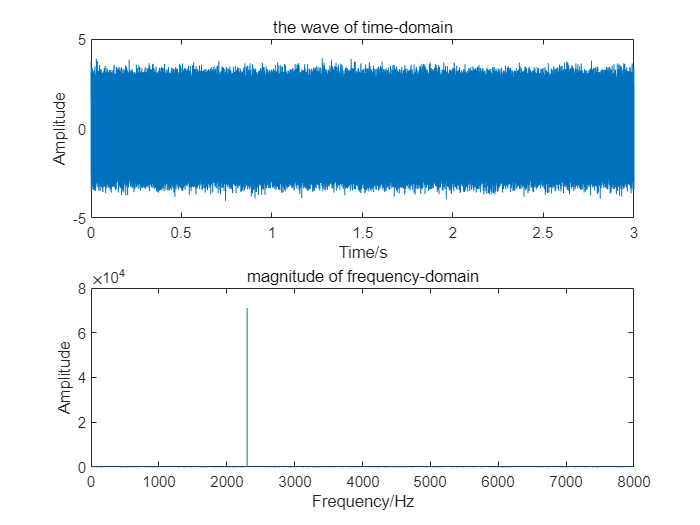

c = 340;                                               % sound velocity  (m)        
fftx = fft(real(X(:,1)));
[N,nSensors] = size(X);
t = (0:N-1)/fs;
f = fs/N*(0:round(N/2)-1);
[~,f_c] = max(abs(fftx(1:round(N/2))));                   
f_c = f_c*fs/N;                                        % center frequency  (Hz)
figure;
subplot(2,1,1);plot(t,real(X(:,1)));
title("the wave of time-domain");xlabel('Time/s');ylabel('Amplitude');
subplot(2,1,2);plot(f,abs(fftx(1:round(N/2))));
title("magnitude of frequency-domain");xlabel('Frequency/Hz');ylabel('Amplitude');

## Array setup

J = nSensors;                                          % number of sensors
n_source = 2;                                          % number of sources
dx = 0.034;                                            % inter-sensor distance in x direction (m)
dy = 0;                                                % sensor distance in y direction (m)                          
Index = linspace(0,J-1,J);
p = (-(J-1)/2 + Index.') * [dx dy];                    % sensor position

## Plot sensor positions

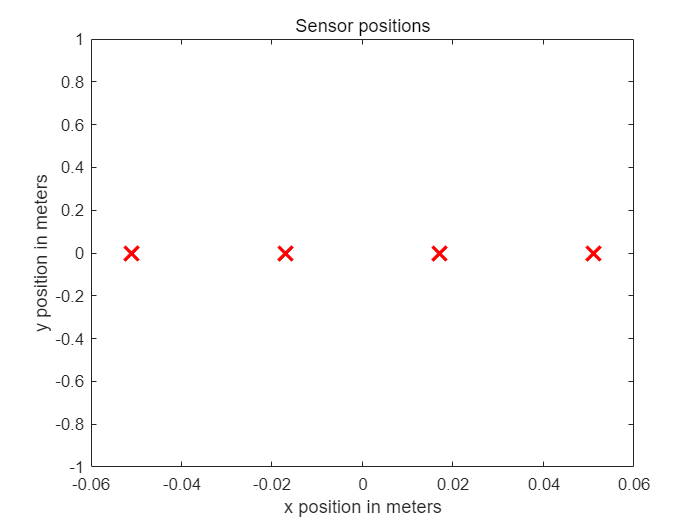

linspec = {'rx','MarkerSize',12,'LineWidth',2};
figure;
plot(p(:,1),p(:,2),linspec{:});
title('Sensor positions');
xlabel('x position in meters');
ylabel('y position in meters');

disp('The four microphones are ready !');

The four microphones are ready !


## DoA estimation (MUSIC)

stride = 1;                                               % determine the angular resolution(deg)
theta = -90:stride:90;                                    % grid
v =  [sind(theta);-cosd(theta)];              % direction vector
a_theta = exp(-1j*2*pi/c*f_c*p*v);                        % steer vector

% implement eigen-decomposition and obtain the pseudo spectrum
R_x = (X.'*(X.')')/N;                                     % autocorrelation estimate
[EV,~] = eig(R_x);     
Un = EV(:,1:end-n_source);                                % noise subspace (columns are eigenvectors), size: J*(J-n_source)       

P_sm = 1./diag(a_theta'*(Un*Un')*a_theta);                % pseudo music power                                  

## Plot the MUSIC pseudo power spectrum

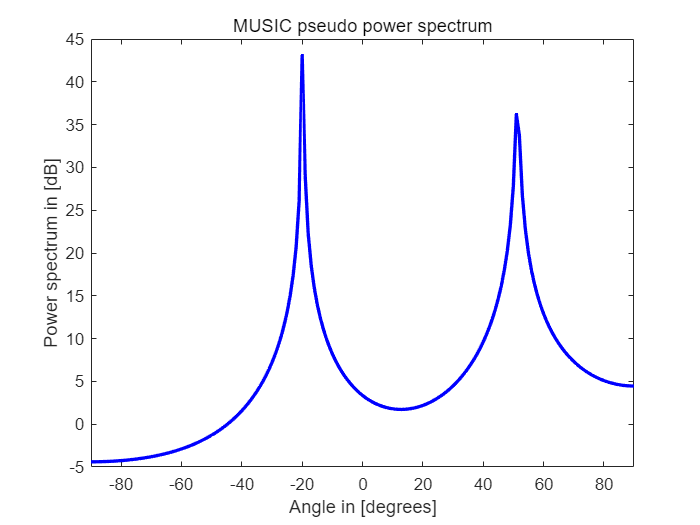

figure;
linspec = {'b-','LineWidth',2};
plot(theta, 10*log10(abs(P_sm)), linspec{:});
title('MUSIC pseudo power spectrum');
xlabel('Angle in [degrees]');
ylabel('Power spectrum in [dB]');
xlim([-90,90]);

## Find the local maximum and visualization

P_middle = abs(P_sm(2:end-1));
P_front = abs(P_sm(1:end-2));
P_back = abs(P_sm(3:end));
logic_front = (P_middle - P_front)>0;
logic_back = (P_middle - P_back)>0;
logic = logic_front & logic_back;
P_middle(~logic) = min(P_middle);
P_local = [abs(P_sm(1));P_middle;abs(P_sm(end))];
[~,doa_Idx] = maxk(P_local,n_source);
doa = theta(doa_Idx);
[~,minIdx] = min(abs(doa));
doa_source = doa(minIdx);
[~,maxIdx] = max(abs(doa));
interfer = doa(maxIdx);
disp(['The desired source DOA with MUSIC is: ',num2str(doa_source),' deg']);

The desired source DOA with MUSIC is: -20 deg


disp(['The interfering DOA with MUSIC is: ',num2str(interfer),' deg']);

The interfering DOA with MUSIC is: 51 deg
